# T2-3. Getting the PSD from data through Daniell estimator

## Introduction

In this tutorial you will learn how to estimate the PSD of a random process from a time series through the Daneill estimator. This technique belongs to the periodogram family of spectral estimators. The time series is assumed to be a realisation of a zero-mean random process. The PSD estimation is obtained by smoothing the sample spectrum.

The dataset employed in this tutorial is 'datasets*/dataset_03_Mann_1V*', which includes a synthetic time series of the longitudinal component of turbulent wind fluctuation (zero mean), according to the Mann's model, and the related true spectrum. This allows comparison between the estimated PSD and the true PSD. 

## Tutorial

First of all, add mVARbox to path, set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters

N_f         = 500;  % number of elements of the frequency vector

N_filter    = 50;   % Number of neighbour values to be used for averaging.
                    % Each averaged value is calculated over a sliding window of 
                    % 'N_filter' neighbour elements.

%%% Plot parameters
font_size           = 20;
figure_position_1   = [0 0 1000 400];
figure_position_2   = [0 0 1000 600];
CC                  = colororder;
color_estimated     = CC(5,:);
color_true          = CC(4,:);
color_sample        = 0.7*[1 1 1];

Load the dataset. It consists of two objects, one in the form of a `data` object, and one in the form of a `S` object. For details related to the fields of these objects, see functions `initialise_data` and `initialise_S`.

load dataset_03_Mann_1V.mat

Have a look at the time series considered. 

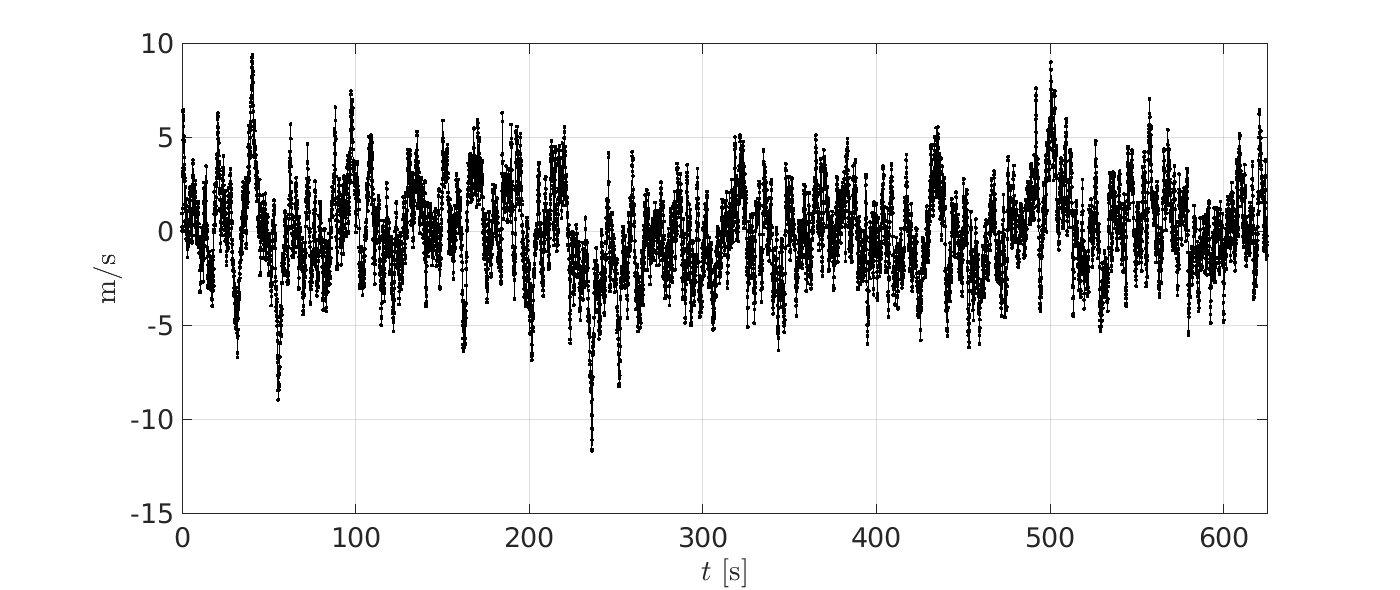

figure

x = data_Mann.x_values;
y = data_Mann.y_values;
plot(x,y,'.-k')

grid on
xlabel('$t$ [s]','Interpreter','latex')
ylabel('m/s','Interpreter','latex')
xlim([0 data_Mann.x_values(end)])

set(gca,'fontsize',font_size)

set(gcf,'position',figure_position_1)

Note the sampling time and the time span of the data. They are useful to define the maximum frequency, $f_{max}$, and the minimum frequency, $f_{min}$. The frequency vector to evaluate the sample spectrum, `f_vector`, will be defined within this frequency range. Log scale will be employed for convenience (see tutorial '*getting_S_from_data_through_sample_spectrum*' for details).

delta_t     = data_Mann.x_parameters.delta_x;   % seconds
t_sim       = delta_t*data_Mann.x_parameters.N; % seconds

f_max       = 1/(2*delta_t);
f_min       = 1/t_sim;

f_vector    = logspace(log10(f_min),log10(f_max),N_f);

Initialise an S object  with the fields required by function `get_S_data_Daniell`. 

S0 = initialise_S('x_values', f_vector);

Compute the PSD of the data. Since the data is univariate, there is no need to specify the column with parameter `k_index` (see details in function get_S_data`_BT`).

S_Daniell = get_S_data_Daniell(data_Mann, S0, N_filter);

Obtain the sample spectrum to include it in the comparison.

S_sample = get_S_data_sample_spectrum(data_Mann, S0);

Plot the obtained PSD together with the true spectrum.

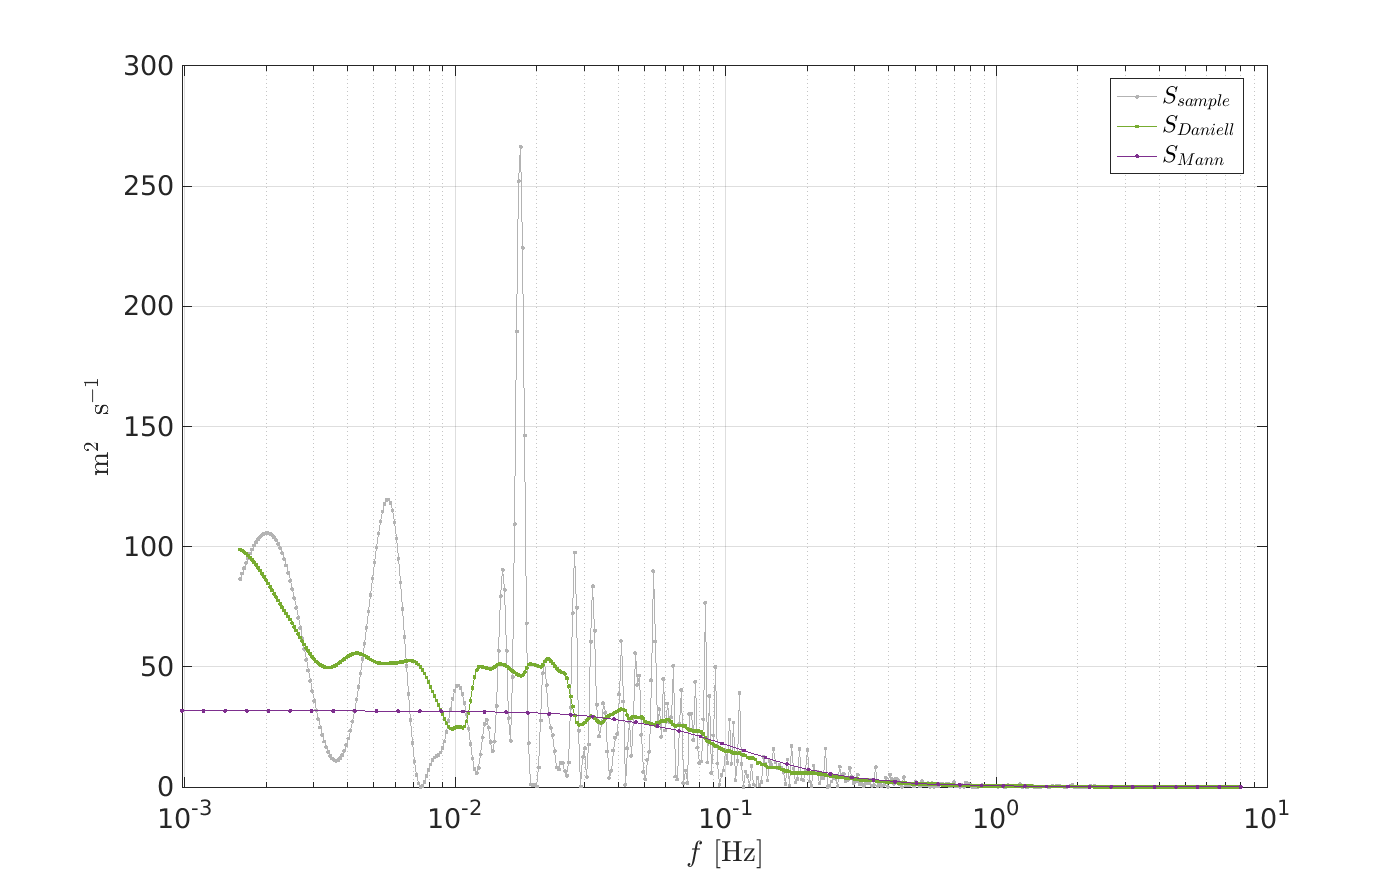

figure

x = S_sample.x_values;
y = S_sample.y_values;
plot(x,y,'.-','color',color_sample)

hold on

x = S_Daniell.x_values;
y = S_Daniell.y_values;
plot(x,y,'.-','color',color_estimated)

x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,y,'.-','color',color_true)

legend({'$S_{sample}$','$S_{Daniell}$','$S_{Mann}$'},...
        'Interpreter','latex',...
        'Location','best')
grid on
xlabel('$f$ [Hz]','Interpreter','latex')
ylabel('m$^2$ \, s$^{-1}$','Interpreter','latex')

set(gca,'fontsize',font_size)
set(gca,'Xscale','log')

set(gcf,'position',figure_position_2)

For the case of wind turbulence, two common representations are the product $f \cdot S$ in log-linear scales, and $S$ in log-log scales.

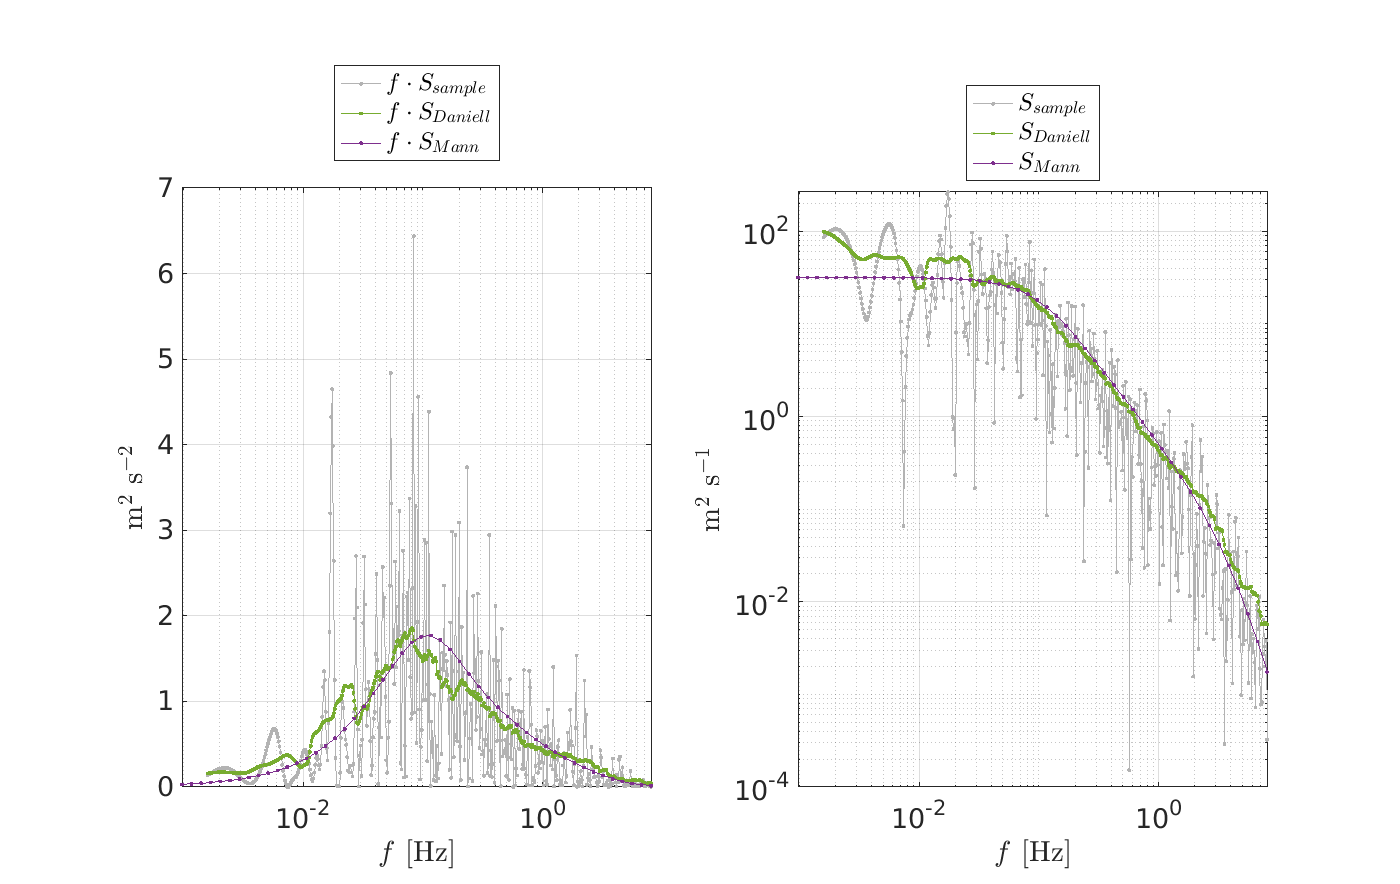

figure


subplot(1,2,1)

x = S_sample.x_values;
y = S_sample.y_values;
plot(x,x.*y,'.-','color',color_sample)

hold on

x = S_Daniell.x_values;
y = S_Daniell.y_values;
plot(x,x.*y,'.-','color',color_estimated)

x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,x.*y,'.-','color',color_true)

grid on
legend({'$f \cdot S_{sample}$','$f \cdot S_{Daniell}$',...
        '$f \cdot S_{Mann}$'},...
        'Interpreter','latex',...
        'Location','northoutside')
xlabel('$f$ [Hz]','Interpreter','latex')
ylabel('m$^2$  s$^{-2}$','Interpreter','latex')
set(gca,'Xscale','log')
set(gca,'fontsize',font_size)


subplot(1,2,2)

x = S_sample.x_values;
y = S_sample.y_values;
plot(x,y,'.-','color',color_sample)

hold on

x = S_Daniell.x_values;
y = S_Daniell.y_values;
plot(x,y,'.-','color',color_estimated)

x = S_Mann.x_values;
y = S_Mann.y_values;
plot(x,y,'.-','color',color_true)





grid on
legend({'$S_{sample}$','$S_{Daniell}$','$S_{Mann}$'},...
        'Interpreter','latex',...
        'Location','northoutside')
xlabel('$f$ [Hz]','Interpreter','latex')
ylabel('m$^2$ s$^{-1}$','Interpreter','latex')

set(gca,'Xscale','log')
set(gca,'Yscale','log')
set(gca,'fontsize',font_size)

set(gcf,'position',figure_position_2)

## Remarks

- Note that the PSD is a continuous function of the frequency, and it can be evaluated at any frequency value. 

- However, the PSD estimated from a discrete time series is periodic for frequencies higher thant $f_{max} $. You can check it just by changing `f_vector` accordingly (and ploting the PSD in x-linear scale). 

- Also, the estimated spectrum for frequencies below $f_{min}$ is likely to be inaccurate because the time simulation of the data, `t_sim`, is not long enough to capture such small frequencies.

- The performance of the Daniell estimator depends greatly on the parameter `N_filter` (actually, on the ratio between `N_filter` and the number of points where the spectrum is estimated, `N_f`). For given `N_f`, small values of `N_filter` lead to high variance (the estimated spectrum resembles more to the sample spectrum) while large values lead to high bias (the estimated spectrum is smooth, but differs notably from the true spectrum). Change this parameter to check this trade-off.